Kp= 5786.7;
Ki=466;
Kd=295;
simulationOutput = sim('A_CruiseControl_Task3');

simulationOutputSignals = simulationOutput.yout;
time = simulationOutput.tout;
input = simulationOutputSignals{1};
output= simulationOutputSignals{2};


t= simulationOutputSignals{2}.Values.time;
d= simulationOutputSignals{2}.Values.Data;
stepinfo(d,t,0,1000)

ans = struct with fields:
         RiseTime: 0
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 1.0069e+03
        Overshoot: 0
       Undershoot: 0.6879
             Peak: 1000
         PeakTime: 0


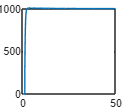

plot(t,d)




simulationStoptime = time(end);
Risetime_HValue = input.Values.Data(end)*0.9; %check if input to check or output
Risetime_LValue = input.Values.Data(end)*0.1;

% for i = output.Values.Data'
%     if(i == Risetime_HValue)
%         currentRisetimeHvalue = i;
%         break;
%     else
%         continue;
%     end
% end
% 
% for i = output.Values.Data'
%     if(i == Risetime_LValue)
%         currentRisetimeLvalue = i;
%         break;
%     else
%         continue;
%     end
% end


%-------Overshoot check---------
for i = output.Values.Data'
    if(i >1100)
        OverShootStatus =1;
        break
    else
        OverShootStatus=0;
        continue
    end
end


%------SteadyStateErrorCheck--------
currentFinalOutputValue = output.Values.Data(end)

currentFinalOutputValue = 1.0002e+03

if(currentFinalOutputValue == input.Values.Data(end))
    SteadyStateErr=0
else
    SteadyStateErr=1
end

SteadyState = 1